N = 100;
Iter = 200;
J = 0.05;
kB = 8.6E-5;
D = zeros(N, N, 2);
D(:,:,2) = ones(N, N, 1);

points = zeros(20,1);
for T = 100:100:3000
    for k=1:Iter
        i = randi(N);
        j = randi(N);
        t = D(i,j,:);
        D(i,j,1) = -1^randi(2) * rand;
        D(i, j, 2) = -1^randi(2) * sqrt(1 - D(i,j,1)^2);
        
        if i < N
           ir = i + 1;
        else
            ir = 2;
        end
        
        if i >= 2
            il = i - 1;
        else
            il = N;
        end
        
        if j < N
            jr = j + 1;
        else
            jr = 2;
        end
        
        if j >= 2
            jl = j - 1;
        else
            jl = N;
        end
       
        E1 = -0.5 * J * (scl(t, D(il,j,:)) + scl(t, D(ir,j,:)) + scl(t, D(i,jr,:)) + scl(t, D(i, jl,:)));
        E2 = -0.5 * J * (scl(D(i,j,:), D(il,j,:)) + scl(D(i,j,:), D(ir,j,:)) + scl(D(i,j,:),D(i,jr,:)) + scl(D(i,j,:),D(i,jl,:)));
        
        if E2 - E1 >= 0
            if rand >= exp(-2*(E2 - E1)/kB/T)
                D(i,j,1) = t(1);
                D(i,j,2) = t(2);
            end
        end
    end
    M = [0 0];
    for i=1:N
        for j=1:N
            M(1) = M(1) + D(i,j,1);
            M(2) = M(2) + D(i,j,2);
        end
    end
    M(1) = M(1)/N^2;
    M(2) = M(2)/N^2;
    points(T/100) = sqrt(M(1) * M(1) + M(2)^2);
end


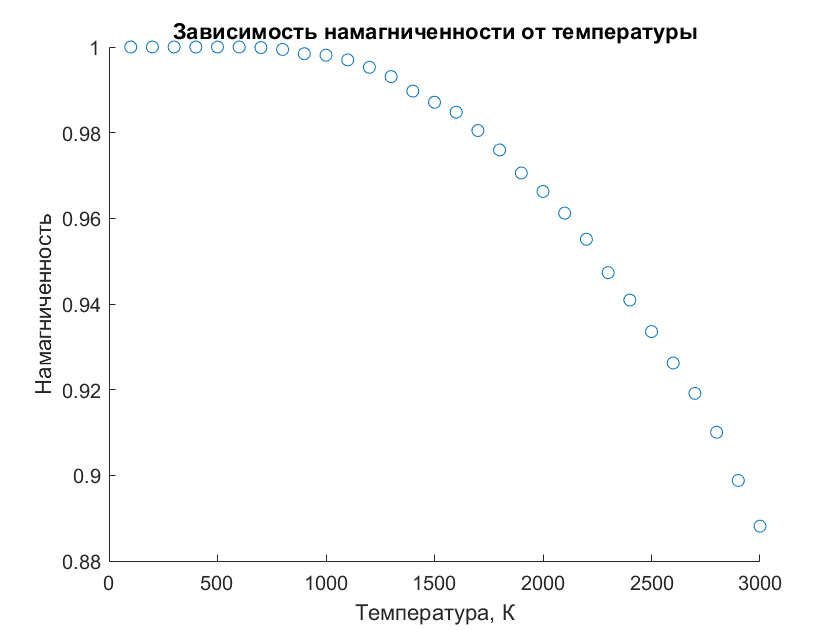


scatter(100:100:3000, points)
title("Зависимость намагниченности от температуры")
xlabel("Температура, К")
ylabel("Намагниченность")

function [r] = scl(a,b)
    r = a(1)*b(1) + a(2)*b(2);
end

